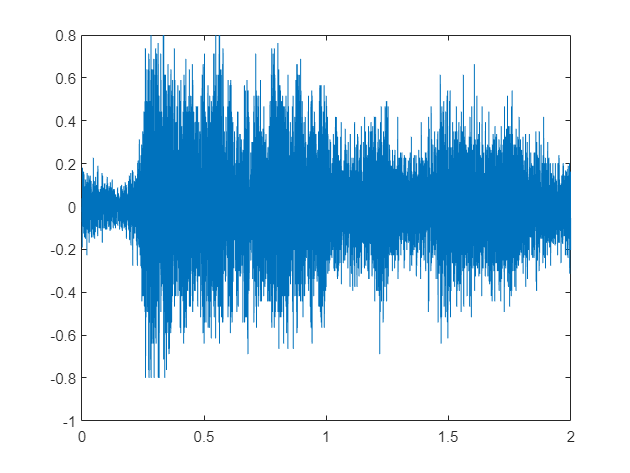

% f = audioread('beethoven.wav');
load handel.mat

filename = 'handel.wav';
audiowrite(filename,y,Fs);
clear y Fs

[y,Fs] = audioread('handel.wav');

num_secs = 2;
num_samps = num_secs*Fs;
f = y(1:num_samps,1);
N = length(f); 
t = linspace(0, num_secs, num_samps);
plot(t, f);

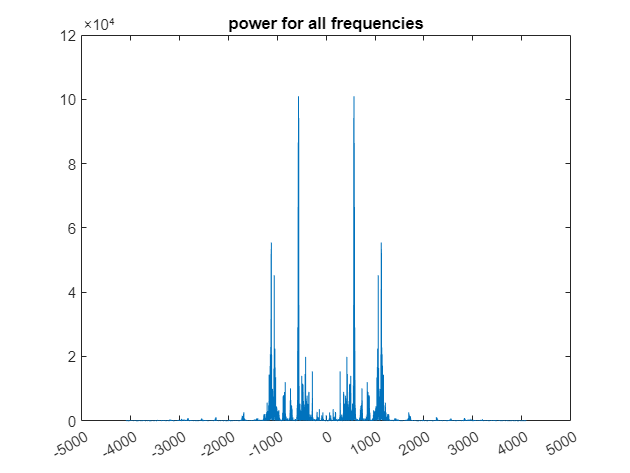



g = fft(f);
P = abs(g).^2;
v = linspace(-Fs/2, Fs/2, num_samps);
plot(v, fftshift(P))
format long g
dx = 10^floor(log10(Fs/2));
xend = ceil(Fs/2/dx)*dx;
xst = -xend;
XT = xst:dx:xend;
xticks(XT)
title('power for all frequencies')

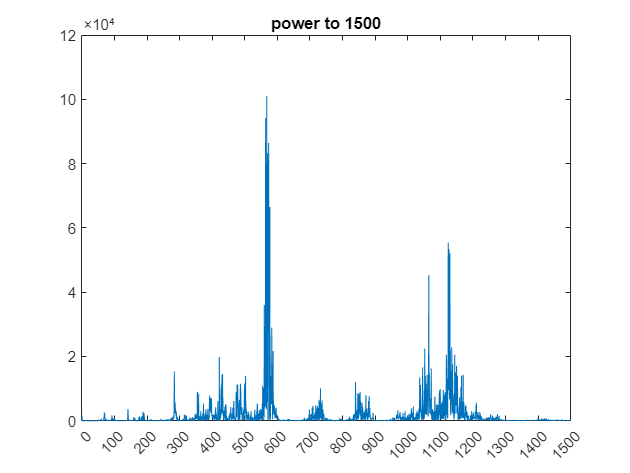


figure
plot(v, fftshift(P))
xlim([0 1500])
xticks(0:100:1500)
title('power to 1500')


% Low pass filter
% y_new = filter(Lowpass_600Hz, y)

% High pass filter
% y_new = filter(Highpass_600Hz, y)

% Band pass
y_new = filter(bandpass_500_800Hz, y)

y_new =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000



% sound(y, Fs)
sound(y_new, Fs)

function Hd = Lowpass_600Hz
%LOWPASS_600HZ Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.11 and Signal Processing Toolbox 8.7.
% Generated on: 10-Jan-2025 21:26:17

% Butterworth Lowpass filter designed using FDESIGN.LOWPASS.

% All frequency values are in Hz.
Fs = 8192;  % Sampling Frequency

N  = 10;   % Order
Fc = 600;  % Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.lowpass('N,F3dB', N, Fc, Fs);
Hd = design(h, 'butter');

end
% [EOF]

function Hd = bandpass_500_800Hz
%BANDPASS_500_800HZ Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.11 and Signal Processing Toolbox 8.7.
% Generated on: 10-Jan-2025 21:45:08

% Butterworth Bandpass filter designed using FDESIGN.BANDPASS.

% All frequency values are in Hz.
Fs = 8192;  % Sampling Frequency

N   = 10;   % Order
Fc1 = 500;  % First Cutoff Frequency
Fc2 = 700;  % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
Hd = design(h, 'butter');

end
% [EOF]

function Hd = Highpass_600Hz

% All frequency values are in Hz.
Fs = 8192;  % Sampling Frequency

N  = 10;   % Order
Fc = 600;  % Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.highpass('N,F3dB', N, Fc, Fs);
Hd = design(h, 'butter');

end
% [EOF]